## Φόρτωση Εικόνων


clc; clear; close all;

% Διαδρομές αρχείων
imageNames = {'dark_road_1.jpg','dark_road_2.jpg','dark_road_3.jpg'};
folderPath = fullfile('Images','Ασκηση 4');


## 4.1 Ιστογράμματα Αρχικών Εικόνων

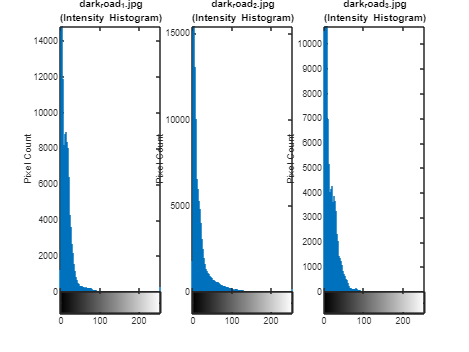


figure('Name','4.1 Ιστογράμματα Αρχικών Εικόνων','NumberTitle','off');
for k = 1:numel(imageNames)
    imgRGB = imread(fullfile(folderPath, imageNames{k}));
    if size(imgRGB,3)==3, imgGray = rgb2gray(imgRGB); else, imgGray = imgRGB; end
    subplot(1,3,k);
    imhist(imgGray);
    title(sprintf('%s\n(Intensity Histogram)', imageNames{k}));
    xlabel('Gray Level'); ylabel('Pixel Count');
end

## 4.2 Ολική Εξίσωση Ιστογράμματος

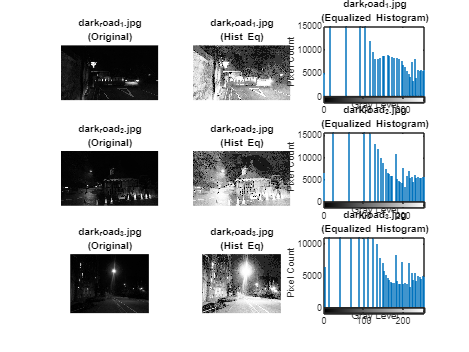


figure('Name','4.2 Ολική Εξίσωση Ιστογράμματος','NumberTitle','off');
for k = 1:numel(imageNames)
    imgRGB = imread(fullfile(folderPath, imageNames{k}));
    if size(imgRGB,3)==3, imgGray = rgb2gray(imgRGB); else, imgGray = imgRGB; end
    imgEq = histeq(imgGray);
    subplot(numel(imageNames),3,3*(k-1)+1);
    imshow(imgGray); title(sprintf('%s\n(Original)', imageNames{k}));
    subplot(numel(imageNames),3,3*(k-1)+2);
    imshow(imgEq);  title(sprintf('%s\n(Hist Eq)', imageNames{k}));
    subplot(numel(imageNames),3,3*(k-1)+3);
    imhist(imgEq);  title(sprintf('%s\n(Equalized Histogram)', imageNames{k}));
    xlabel('Gray Level'); ylabel('Pixel Count');
end

## 4.3 Τοπική Εξίσωση Ιστογράμματος

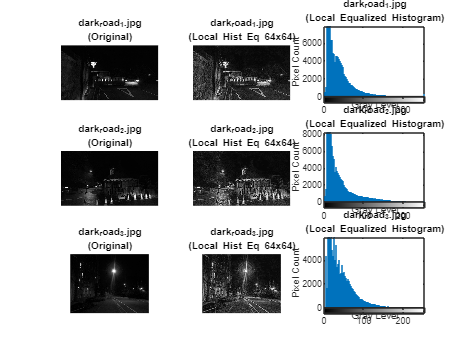


% Επιλογή μεγέθους τοπικού παραθύρου για αντιστάθμιση (TileGridSize)
localSize = [64 64];  % παράθυρο 64×64 pixels
clipLimit = 0.01;      % παράμετρος αποκοπής για αποφυγή υπερτονισμού

figure('Name','4.3 Τοπική Εξίσωση Ιστογράμματος','NumberTitle','off');
for k = 1:numel(imageNames)
    imgRGB = imread(fullfile(folderPath, imageNames{k}));
    if size(imgRGB,3)==3, imgGray = rgb2gray(imgRGB); else, imgGray = imgRGB; end
    % Εφαρμογή local histogram equalization (CLAHE)
    imgLocalEq = adapthisteq(imgGray, 'NumTiles', localSize, 'ClipLimit', clipLimit);
    % Εμφάνιση αρχικής, τοπικά εξισωμένης & ιστογράμματος
    subplot(numel(imageNames),3,3*(k-1)+1);
    imshow(imgGray);      title(sprintf('%s\n(Original)', imageNames{k}));
    subplot(numel(imageNames),3,3*(k-1)+2);
    imshow(imgLocalEq);   title(sprintf('%s\n(Local Hist Eq %dx%d)', imageNames{k}, localSize));
    subplot(numel(imageNames),3,3*(k-1)+3);
    imhist(imgLocalEq);   title(sprintf('%s\n(Local Equalized Histogram)', imageNames{k}));
    xlabel('Gray Level'); ylabel('Pixel Count');
end